% Define the number of samples
num_samples = 50;  % Adjust as needed

% Define the limits for both dimensions
lower_limit = 0;
upper_limit = 8;

% Generate Latin hypercube samples
lhs_samples = lhsdesign(num_samples, 2, 'criterion', 'maximin', 'iterations', 200)

lhs_samples =     0.8803    0.8299
    0.0339    0.0703
    0.2659    0.6375
    0.5710    0.4140
    0.4612    0.7173
    0.6924    0.7590
    0.4422    0.1123
    0.9151    0.4452
    0.9381    0.4869
    0.6157    0.5208



% Scale the samples to fit within the limits
lhs_samples = lhs_samples * (upper_limit - lower_limit) + lower_limit;

GlcNAc_I = lhs_samples(:,1);
GlcUA_I = lhs_samples(:,2);
[Mw_pred,Mw_sd,Mw_int] = predict(gprMdl_Mw, [GlcNAc_I(:), GlcUA_I(:)]);
[PDI_pred,~,PDI_int] = predict(gprMdl_pdi, [GlcNAc_I(:), GlcUA_I(:)]);
data = [GlcNAc_I GlcUA_I Mw_pred PDI_pred]

data =     7.0425    6.6391   80.5198    1.5461
    0.2710    0.5626  128.7670    1.1760
    2.1274    5.1003   57.4648    1.4163
    4.5676    3.3120   50.9253    1.5342
    3.6894    5.7382   62.7575    1.5583
    5.5393    6.0716   73.2680    1.6182
    3.5376    0.8985   56.9824    1.2956
    7.3209    3.5617   50.2834    1.4969
    7.5046    3.8951   55.1911    1.5042
    4.9258    4.1667   56.8514    1.5959


tableRandom = table(PDI_pred,Mw_pred,GlcNAc_I,GlcUA_I,'VariableNames',{'PDI','MW','UDP-GlcNAc','UDP-GlcUA'});


load tablaOutput.mat
data = [tableRandom.("UDP-GlcNAc") tableRandom.("UDP-GlcUA") tableRandom.MW tableRandom.PDI];

mu_v = data(:,3);
std_v =sqrt ((data(:,4) - 1).*mu_v.^2);

cm = parula(50)

cm =     0.2422    0.1504    0.6603
    0.2526    0.1698    0.7201
    0.2618    0.1909    0.7763
    0.2699    0.2121    0.8308
    0.2756    0.2372    0.8753
    0.2794    0.2654    0.9095
    0.2811    0.2942    0.9362
    0.2810    0.3228    0.9579
    0.2787    0.3509    0.9752
    0.2728    0.3795    0.9878


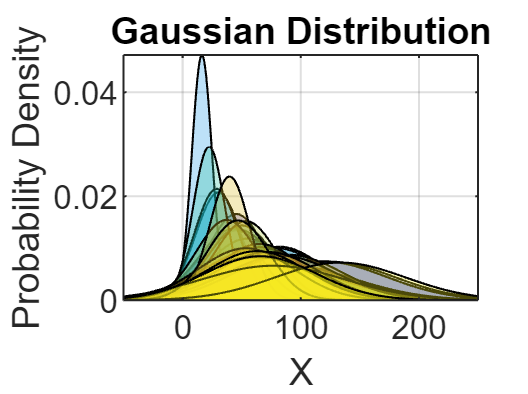



clf
% Generate x-values for plotting
alphas = 0.3;
for i=1:50
    mu = mu_v(i);
    sigma = std_v(i);
    x = linspace(mu - 4*sigma, mu + 4*sigma, 1000);
    % Compute the probability density function (PDF) of the normal distribution
    pdf_normal = normpdf(x, mu, sigma);

    % Plot the Gaussian distribution as a filled plot wit transparency
    fill(x, pdf_normal,cm(i,:), 'FaceAlpha', alphas);
    hold on;

    % Plot the PDF curve for reference
    %plot(x, pdf_normal, 'b', 'LineWidth', 2);
    xlabel('X');
    ylabel('Probability Density');
    title('Gaussian Distribution');
    grid on;

end
xlim([-50 250])